% guided_quantile_lasso_simulation.m
% Simulazione sparsity (p=40, n=1000)
% Usa linprog per risolvere i problemi di Quantile Regression (LP formulation).
% Richiede Optimization Toolbox (linprog).

% Simulazione di Monte Carlo
clear; close all; rng(12345);
nRep = 10;

nonzeros=zeros(1,nRep);

mse_model1 = zeros(1,nRep);
mse_model2 = zeros(1,nRep);
mse_model3 = zeros(1,nRep);
mse_model4 = zeros(1,nRep);

L=zeros(1,nRep);
L_qr_en = zeros(1,nRep);
L_en = zeros(1,nRep);
L_gl  = zeros(1,nRep);

for i = 1:nRep

%% impostazioni
n = 1000;
p = 40;
tau = 0.5;                 % quantile
epsilon = 1e-3;            % stabilizzatore per i pesi
Kcv = 5;                   % K per K-fold CV su lambda
% lambdaGrid = logspace(-3, 0, 20); % griglia lambda che restituisce lambda
% = 1, quindi restirngiamo la griglia nella zona di maggiore interesse. In
% questo caso la espandiamo verso valori più grandi
lambdaGrid = logspace(-3,2,30);

%% 1) Genera dati (design correlato + beta sparse + rumore heavy-tailed)
rho = 0.3;
% Matrice di covarianza Toeplitz con correlazione rho
Sigma = toeplitz(rho.^(0:p-1));
% campiona X ~ N(0, Sigma)
X = mvnrnd(zeros(1,p), Sigma, n);

% Introduce contaminazione nei dati
Perc_Contaminazione = 0.1;
Contaminazione = 1.5;
numContaminated = round(Perc_Contaminazione * n);
contaminatedIndices = randperm(n, numContaminated);
X(contaminatedIndices) = X(contaminatedIndices) * Contaminazione;

% vettore beta vero (sparse)
k_nonzero = 6;
idx = randperm(p, k_nonzero);
beta_true = zeros(p,1);
% alcuni valori non nulli (segni e magnitudo casuali)
beta_true(idx) = [2.0; -1.8; 1.5; -2.5; 3.0; -1.2];

u = rand(n,1);        % rumore uniforme in [0,1]
u = u - mean(u);      % centro attorno a 0

idx_spike = randperm(n,10);   % scelgo 10 indici a caso
u(idx_spike) = u(idx_spike) * 10;   % aggiungo spike

Y = X * beta_true + u;

%fprintf('Dati generati: n=%d, p=%d, nonzero truth=%d\n', n, p, k_nonzero);

%% 2) Stima marginale per ogni j: Y = alpha_j + r_j * X_j + resid (quantile regression)
r = zeros(p,1);
alpha_marg = zeros(p,1);

%fprintf('Stimo regressioni marginali per j=1..%d (quantile=%g)\n', p, tau);
for j = 1:p
    Xj = X(:, j);
    % uso la funzione penalized_qr_lp con lambda=0 (equiv. quantile regression non penalizzata)
    [a_hat, beta_hat] = penalized_qr_lp([ones(n,1) Xj], Y, tau, 0, [0;0]); 
    % notare che la funzione ritorna 'beta' corrispondente alle colonne fornite,
    % quindi beta_hat(1) è intercept alpha, beta_hat(2) è slope rispetto a Xj
    alpha_marg(j) = a_hat;
    r(j) = beta_hat(2);
end

%% 3) Calcola i pesi w_j = 1/(epsilon + |r_j|)
w = 1 ./ (epsilon + abs(r));
%fprintf('Pesi calcolati (epsilon=%g). Esempio primi 8 pesi:\n', epsilon);
%disp(w(1:min(8,p))');

%% 4) Cross-validation per scegliere lambda nella penalized quantile regression pesata
% Modello: Y ~ X (senza intercept nella X: lo inserisco internamente nella funzione)
%fprintf('Cross-validation K=%d per lambda grid (%d valori)\n', Kcv, numel(lambdaGrid));
cvLoss = zeros(numel(lambdaGrid),1);

% crea folds
idxperm = randperm(n);
foldSizes = floor(n/Kcv) * ones(1,Kcv);
remainder = n - sum(foldSizes);
for k=1:remainder, foldSizes(k)=foldSizes(k)+1; end
folds = cell(Kcv,1);
start = 1;
for k=1:Kcv
    fsz = foldSizes(k);
    folds{k} = idxperm(start:start+fsz-1);
    start = start+fsz;
end

for li = 1:numel(lambdaGrid)
    lam = lambdaGrid(li);
    loss_k = zeros(Kcv,1);
    for k = 1:Kcv
        valIdx = folds{k};
        trainIdx = setdiff(1:n, valIdx);
        Xtr = X(trainIdx,:);
        Ytr = Y(trainIdx);
        Xval = X(valIdx,:);
        Yval = Y(valIdx);
        % stima sul training con pesi w
        [~, beta_hat] = penalized_qr_lp([ones(size(Xtr,1),1) Xtr], Ytr, tau, lam, [0; w(:)]);
        % predizione su val (attenzione: la funzione ritorna beta includendo intercept)
        preds = [ones(size(Xval,1),1) Xval] * beta_hat;
        loss_k(k) = pinball_loss(Yval - preds, tau);
    end
    cvLoss(li) = mean(loss_k);
    %fprintf('lambda = %.4g, CV pinball = %.6f\n', lam, cvLoss(li));
end

[~, bestIdx] = min(cvLoss);
lam_star = lambdaGrid(bestIdx);
%fprintf('Lambda selezionata (min CV): %.4g\n', lam_star);

%% 5) Stima finale guidata con lam_star e pesi w
[a_final, beta_final] = penalized_qr_lp([ones(n,1) X], Y, tau, lam_star, [0; w(:)]);
% beta_final: [intercept; beta_1; ... beta_p]

nz_thresh = 1e-5; % coefficienti diversi da zero ma troppo piccoli per essere significativi
nonzeros(i) = numel(find(abs(beta_final(2:end)) > nz_thresh));

%fprintf('Numero di coefficienti non-zero stimati: %d (soglia %g)\n', numel(nonzeros), nz_thresh);
%fprintf('Indici nonzero stimati: '); fprintf('%d ', nonzeros); fprintf('\n');

% mostra confronto con beta_true
%disp('Confronto beta_true vs beta_hat (primi 12):');
%disp(table((1:p)', beta_true, beta_final(2:end), 'VariableNames', {'j','beta_true','beta_hat'}));
% Residui
% Calcola i residui
residuals = Y - X * beta_final(2:end);

% Calcoliamo i valori teorici
yhat1 = X * beta_final(2:end)+ residuals;
mse_model1(i) = mean((Y - yhat1).^2);

%fprintf('Errore quadratico medio sui residui: %.4f\n', mean(residuals.^2));
L(i) = pinball_loss(residuals, tau);
%fprintf('Pinball loss per modello:\n');

%% 6) Grafici di confronto e calcoli di rendimento percentuale


% Errore percentuale solo sui coefficienti "veri" (nonzero)

nz_idx = find(beta_true ~= 0);

perc_err = abs(beta_final(1+ nz_idx) - beta_true(nz_idx)) ./ abs(beta_true(nz_idx)) * 100;

fprintf('Errore percentuale medio sui coefficienti veri: %.2f %%\n', mean(perc_err));

% Grafico: beta_true vs beta_hat

figure;

bar([beta_true, beta_final(2:end)]);

legend({'beta true','beta stimato'},'Location','best');

xlabel('Indice coefficiente j');

ylabel('Valore');

title('Confronto beta vero vs stimato (guided QR)');

% Grafico: errori percentuali

figure;

bar(nz_idx, perc_err);

xlabel('Indice coefficiente (solo non-zero)');

ylabel('Errore percentuale (%)');

title('Errore percentuale sui coefficienti veri');

ylim([0 100]);

% Grafico: andamento CV loss su lambda

figure;

semilogx(lambdaGrid, cvLoss, '-o','LineWidth',1.5);

xlabel('\lambda');

ylabel('CV Pinball loss');

title('Cross-validation Pinball loss');

grid on;

## Confronto con altri modelli

### Quantile Regression con Elastic Net (QR + EN)

Xfull = [ones(n,1) X]; % Includiamo l'intercetta
weights = [0; ones(p,1)]; % niente penalizzazione sull'intercetta
[a_qr_en, beta_qr_en] = penalized_qr_en(Xfull, Y, tau, lam_star, 0.5, weights);

res_qr_en = Y - Xfull*beta_qr_en;
L_qr_en(i) = pinball_loss(res_qr_en, tau);

%fprintf('Quantile Reg + EN: %.4f\n', L_qr_en);

yhat2 = X * beta_qr_en(2:end)+ res_qr_en;
mse_model2(i) = mean((Y - yhat2).^2);


figure;

boxplot([residuals, res_qr_en],'Labels', {'Adaptive QR','QR + EN'});

ylabel('Residui');

title('Confronto residui tra modelli');

figure;
subplot(2,1,1)
bar(residuals);
ylabel('Residui AQR');
subplot(2,1,2)
bar(res_qr_en);
ylabel('Residui');
title('Residui QR + EN');
title('Residui del modello finale');

figure;
subplot(2,1,1);
hold on
plot(residuals,'LineStyle','none','Marker','.','MarkerSize',20)
yline(0)
hold off
subplot(2,1,2);
hold on
plot(res_qr_en,'LineStyle','none','Marker','.','MarkerSize',20)
yline(0)
hold off

### OLS + Elastic Net (EN)


$$\[
\min_{\beta} \;
\underbrace{\frac{1}{2n} \, \|Y - X\beta\|_2^2}_{\text{OLS (errore quadratico medio)}}
\;+\;
\underbrace{\lambda \Big( \alpha \|\beta\|_1 + (1-\alpha)\|\beta\|_2^2 \Big)}_{\text{Penalizzazione Elastic Net}}
\]
$$


% Stima del parametro Alpha ottimale tramite CV folds
alphas = 0.0001:0.1:1;       % valori di Alpha da testare
nAlpha = length(alphas);

pinball_losses = zeros(nAlpha,1);

for f = 1:nAlpha
    alpha = alphas(f);
    
    % Elastic Net con lasso
    [B, FitInfo] = lasso(X, Y, 'Alpha', alpha, 'Lambda', lam_star);
    beta_en = [FitInfo.Intercept; B];  % ricostruisco beta completo
    
    % residui
    Xfull = [ones(size(X,1),1), X];
    res_en = Y - Xfull*beta_en;
    
    % pinball loss
    pinball_losses(f) = pinball_loss(res_en, 0.5); % o altro tau
end

yhat3 = X * beta_en(2:end)+ res_en;
mse_model3(i) = mean((Y - yhat3).^2);

% Trovo alpha ottimale
[L_en(i), idx] = min(pinball_losses);
alpha_best = alphas(idx);

%fprintf('Alpha ottimale: %.2f, pinball loss = %.4f\n', alpha_best, pinball_losses(idx));
x = 1:n;                    % ascisse corrispondenti ai residui
y = 5 * sin(2*pi*35*x/n);           % valori sinusoidali da plottare


figure;

bar(res_en);                 % barre dei residui

hold on;

plot(x, y, 'LineWidth', 0.5,'Color','r','LineStyle','-'); % linea sinusoidale rossa sopra

hold off;

ylabel('Residui OLS + EN');

xlabel('Indice osservazione');

title('Residui con linea sinusoidale sovrapposta');

figure;

hold on

plot(res_en,'LineStyle','none','Marker','.','MarkerSize',20)

yline(0)

hold off

### OLS + Guided LASSO

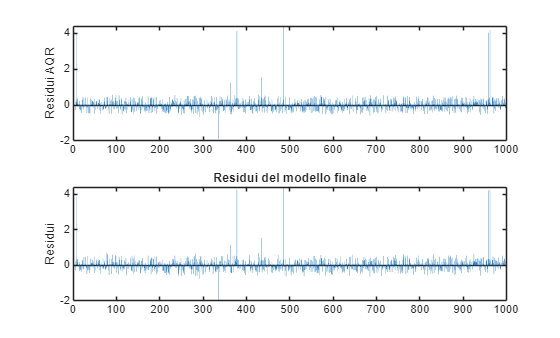

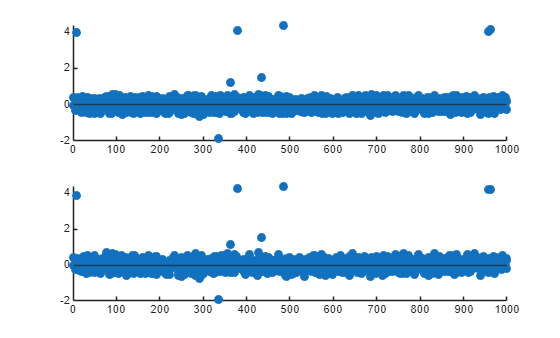

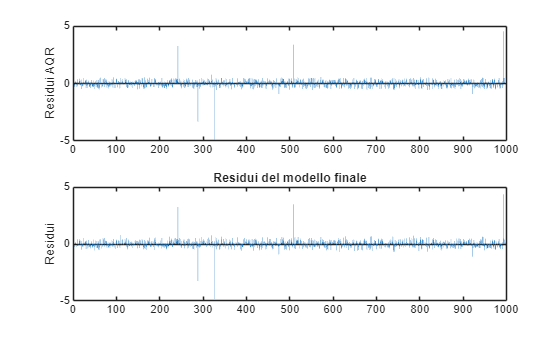

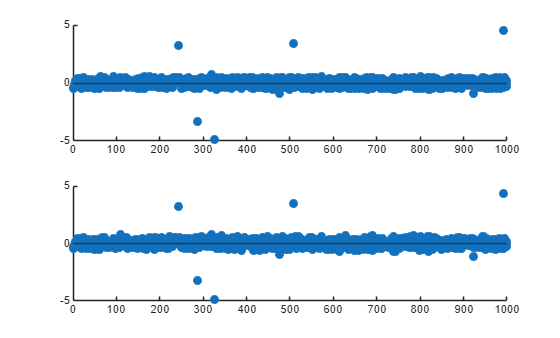

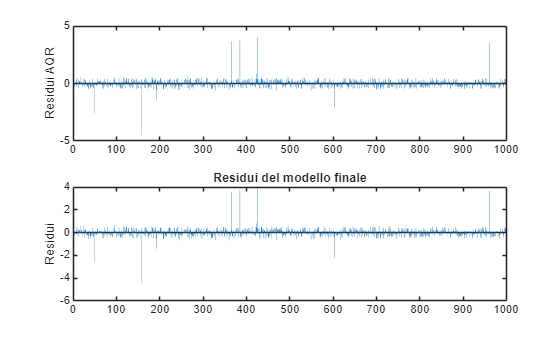

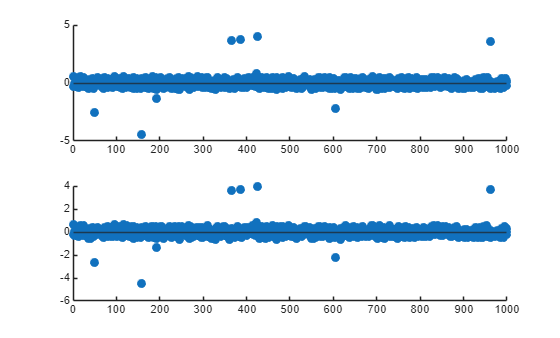

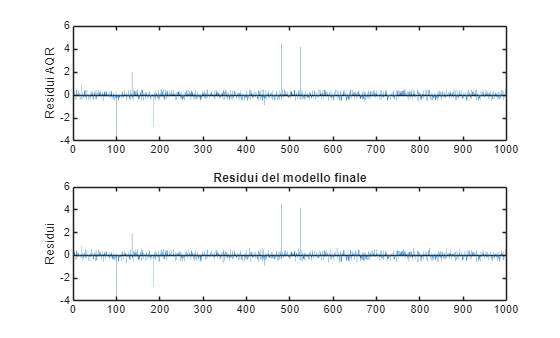

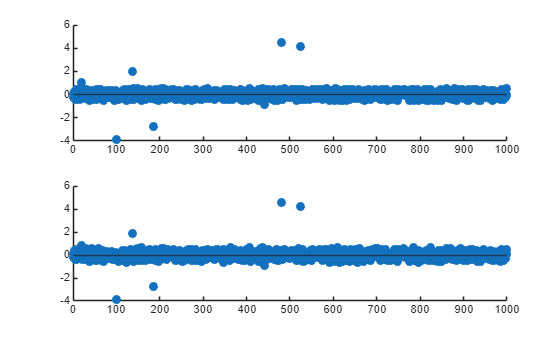

% Step 1: OLS
beta_ols = regress(Y, Xfull);

% Step 2: pesi adattivi (escludendo l'intercetta)
gamma = 1;
eps_val = 1e-3;
weight = 1 ./ (abs(beta_ols).^gamma + eps_val); 
weight(1) = 0; % non penalizziamo intercept

% Step 3: chiamata alla funzione QR penaliz ma con l'utilizzo di pesi OLS
[a_hat, beta_gl] = penalized_qr_lp(Xfull, Y, tau, lam_star, weight);

% Residui
res_gl = Y - Xfull * beta_gl;

yhat4 = X * beta_gl(2:end)+ res_gl;
mse_model4(i) = mean((Y - yhat4).^2);

% Pinball loss
L_gl(i) = pinball_loss(res_gl, tau);
end

## Grafici di confronto tra i modelli

fprintf('MSE medio Modello 1: %.4f\n', mean(mse_model1));

MSE medio Modello 1: 0.0000


fprintf('MSE medio Modello 2: %.4f\n', mean(mse_model2));

MSE medio Modello 2: 0.0001


fprintf('MSE medio Modello 3: %.4f\n', mean(mse_model3));

MSE medio Modello 3: 0.0204


fprintf('MSE medio Modello 4: %.4f\n', mean(mse_model4));

MSE medio Modello 4: 0.0000


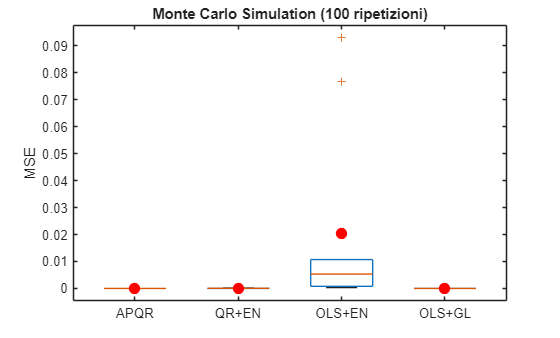


figure;
boxplot([mse_model1', mse_model2', mse_model3', mse_model4'], 'Labels', {'APQR','QR+EN','OLS+EN','OLS+GL'},'Widths', 0.6);
ylabel('MSE');
hold on;
means = [mean(mse_model1), mean(mse_model2), mean(mse_model3), mean(mse_model4)];
plot(1:4, means, 'ro','MarkerSize',8,'MarkerFaceColor','r');
hold off;
title('Monte Carlo Simulation (100 ripetizioni)');

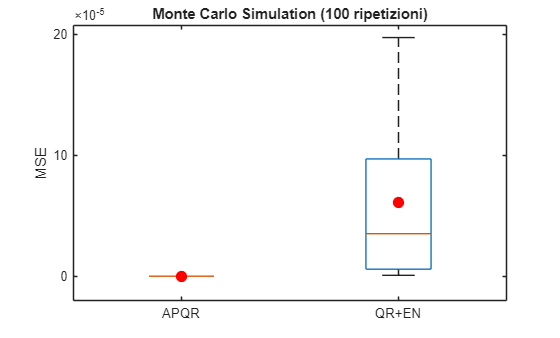


figure;
boxplot([mse_model1', mse_model2'], 'Labels', {'APQR','QR+EN'});
ylabel('MSE');
hold on;
means1 = [mean(mse_model1), mean(mse_model2)];
plot(1:2, means1, 'ro','MarkerSize',8,'MarkerFaceColor','r');
hold off;

title('Monte Carlo Simulation (100 ripetizioni)');

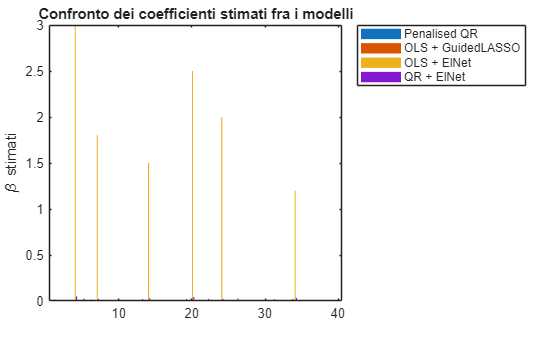

models = {'Penalised QR', 'OLS + GuidedLASSO', 'OLS + ElNet', 'QR + ElNet'};
betas = {abs(beta_true-beta_final(2:end)), abs(beta_true-beta_gl(2:end)), abs(beta_true-beta_en(2:end)), abs(beta_true-beta_qr_en(2:end))};
residui = {residuals, res_gl, res_en, res_qr_en};
losses = [L, L_gl, L_en, L_qr_en];

p = length(betas{1});  % numero coefficienti (incluso intercept)
nModels = numel(models);

%% 1) Grafico coefficiente stimati
figure;
% barra affiancata: ogni gruppo = coefficienti, ogni modello una barra
beta_mat = zeros(p, nModels);
for k = 1:nModels
    beta_mat(:,k) = betas{k};
end
bar(beta_mat);
legend(models, 'Location','bestoutside');
ylabel('\beta stimati');
title('Confronto dei coefficienti stimati fra i modelli');

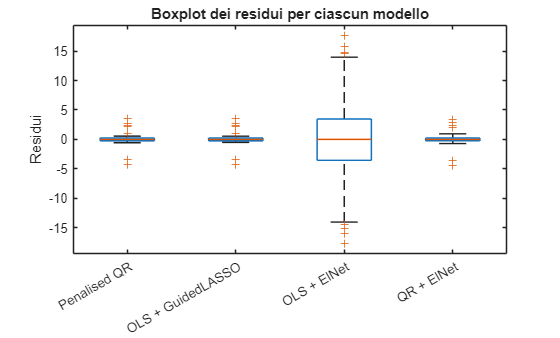


%% 2) Boxplot / confronto residui
figure;
% concateno residui in matrice per boxplot
all_res = [];
group = [];
for k = 1:nModels
    r = residui{k};
    all_res = [all_res; r(:)];
    group = [group; k*ones(length(r),1)];
end
boxplot(all_res, group, 'Labels', models);
ylabel('Residui');
title('Boxplot dei residui per ciascun modello');

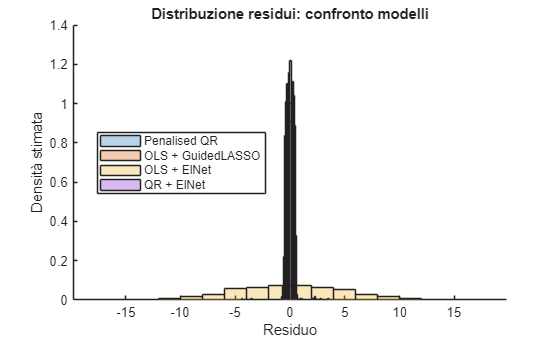


%% 3) Istogrammi residui (confronto densità)
figure;
hold on;
colors = lines(nModels);
for k = 1:nModels
    r = residui{k};
    % uso funzione "histogram" con normalizzazione
    histogram(r, 'Normalization','pdf', 'FaceColor', colors(k,:), 'FaceAlpha', 0.3);
end
hold off;
legend(models, 'Location','best');
xlabel('Residuo');
ylabel('Densità stimata');
title('Distribuzione residui: confronto modelli');

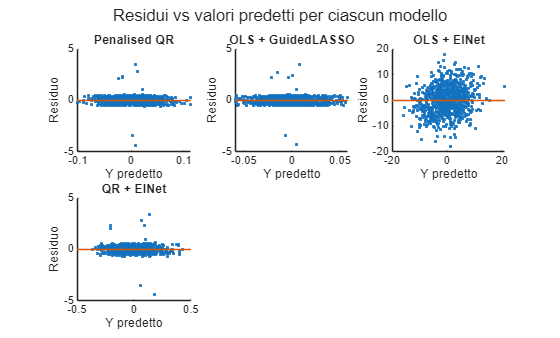

%% 5) (Opzionale) Residui vs predetti
figure;
for k = 1:nModels
    subplot(2,3,k);
    yhat = X * betas{k};
    scatter(yhat, residui{k}, '.');
    xlabel('Y predetto');
    ylabel('Residuo');
    title(models{k});
    refline(0,0);  % linea zero
end
sgtitle('Residui vs valori predetti per ciascun modello');